# Pendulum exercise

## 1. Introduction & System Modeling

### 1.1 System Description and Parameters

This exercise demonstrates Active Disturbance Rejection Control (ADRC) for a pendulum system. The controller must regulate the pendulum angle to a setpoint while rejecting disturbances and handling sensor noise.

System Parameters:

- Pendulum tip mass: M = 0.4 kg

- Rod length: l = 0.3 m

- Viscous friction coefficient: c = 0.1

- Gravitational acceleration: g = 9.81 m/s²

Control Specifications:

- Settling time (10% of setpoint): < 5 seconds (initial), < 2 seconds (final)

- Disturbance rejection: oscillations within 10% of setpoint

- Control effort: torque oscillations within 1 Nm peak-to-peak

- Setpoint: θ_setpoint = 1 rad

Disturbance Configuration:

- Eccentric mass: m_e = 0.2 kg at radius r_e = 0.02 m

- Disturbance frequency: ω_m = 20 rad/s

- Centrifugal force: Fc = m_e * r_e * ω_m²

clear all
close all
clc

% Initialize simulation variables
theta_setpoint = 1;  % [rad] set-point for the pendulum angular position
debug_mode = 0;      % debug mode flag (1=debug, 0=normal). If the debug mode is activated the controller plant becomes a pure double integrator
manual_control_flag = 1;    % flag to switch from manual to ADRC control (1=manual, 0=adrc)
u_manual = 0;   % [Nm] manual control action (motor torque), it is applied only if manual control is activated


% Simulation settings
Tsim = 10;
rel_tol= 1e-6;

% Initialize pendulum variables
M = 0.4;    % [kg] mass of the pendulum tip
l = 0.3;    % [m] length of the pendulum rod
c = 0.1;    % viscous friction coefficient
g = 9.81;    % [m/s^2] acceleration due to gravity

% Sensor noise
pow = 0;
Ts = 1e-3;

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 


% Disturbance settings
m_e = 0.2;     % [kg] eccentric mass
r_e = 0.02;    % [m] eccentric radius
omega_m = 20; % [rad/s] eccentric shaft angular velocity
Fc = m_e*r_e*omega_m^2;     % [N] centrifugal force
disturbance_flag = 0;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)
T_dist = 5;     % [s] time at which the motor is turned on


## 2. ADRC Design & Implementation

### 2.1 Controller Tuning Parameters

The ADRC controller consists of a state-feedback controller and an Extended State Observer (ESO) that estimates both system states and total disturbance.

% ADRC tuning
% Desired closed-loop response characteristics
T_settle = 2;    %   [s] settling time 98%
xi = 1;     % desired closed-loop damping
omega_c = 6/T_settle;   % [rad/s] desired closed-loop bandwidth

% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
omega_o = 10*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


### **2.2 Debug Mode: Validation with Ideal Plant**

Before controlling the actual pendulum, we validate our ADRC implementation on a simplified double-integrator plant where the ESO model perfectly matches the plant dynamics.

**Objective:** Verify that the simulated response matches the theoretical second-order response, confirming correct implementation of the ESO and control law.

**Expected Result:** Perfect overlap between simulated and theoretical responses, with ESO accurately estimating all states and zero total disturbance (no model mismatch).

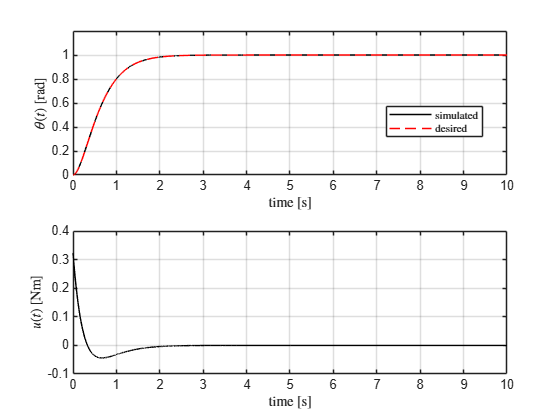

debug_mode = 1;      % debug mode flag (1=debug, 0=normal)

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

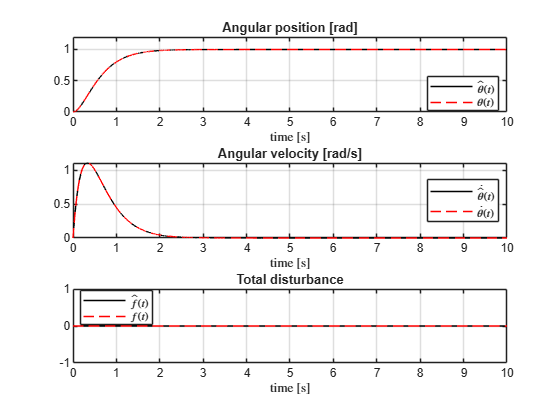

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

**Observation:** The responses match perfectly. Furthermore, the ESO's state estimates (`theta_hat`, `theta_hat_dot`) align exactly with the plant's true states, and the estimated total disturbance `f_hat` is zero. This is expected because the plant model and the ESO's internal model are identical, leaving no "unmodeled" dynamics to reject.

## 3. Pendulum Model Validation

### 3.1 Open-Loop Response Verification

#### **Test 1:** Free Oscillation from Non-Zero Angle

- Initial condition: `θ = π/2 rad`

- Control: Manual mode with `u_manual = 0`

- Disturbance: Enabled at t = 5s

**Expected Behavior:** Damped oscillations settling to vertical position (θ = 0) due to gravity and friction, with visible disturbance effects after t = 5s.

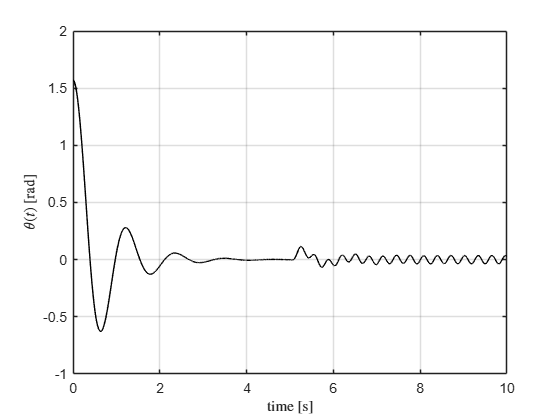

debug_mode = 0;      % debug mode flag (1=debug, 0=normal)
manual_control_flag = 1; % flag to switch from manual to adrc control (1=manual, 0=adrc)

theta_init = pi/2; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

disturbance_flag = 1;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t_ol = simout.tout;
theta_ol = simout.yout{1}.Values.Data;

% Plot the results of the simulation
figure;
plot(t_ol, theta_ol, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;

**Observation:** The pendulum swings and settles as expected, confirming the basic dynamics (gravity, inertia, friction) are implemented correctly. The disturbance at t=5s creates a clear oscillation.

#### **Test 2:** Static Torque Balance

- Initial condition: `θ = π/2 rad`

- Control: Constant torque `u_manual = M*g*l`

- Disturbance: Disabled

**Expected Behavior:** Pendulum remains steady at `π/2 rad because the` applied torque balances gravitational torque.

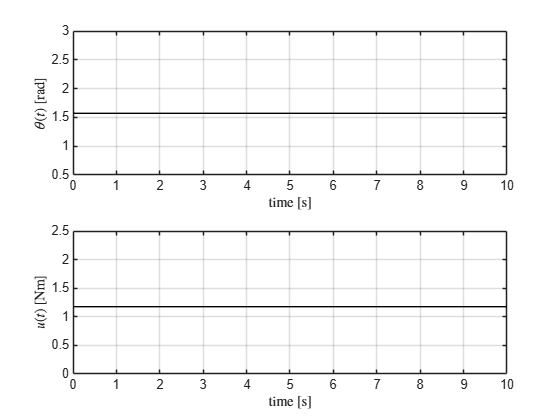

u_manual = M*g*l;
disturbance_flag = 0;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

#### Test 3: Dynamic Torque Balance

- Initial condition: `θ = 0 rad`

- Control: Constant torque `u_manual = M*g*l/2`

- Disturbance: Disabled

**Expected Behavior:** Pendulum settles at non-zero angle where applied torque balances gravitational torque.

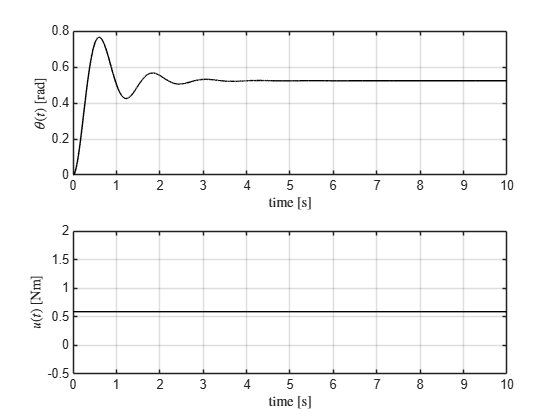

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

u_manual = (M*g*l)/2;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

**Observation:** The pendulum moves and settles at a non-zero angle, confirming that the input (motor torque) correctly influences the plant model.

We also check the states estimated by the ESO.

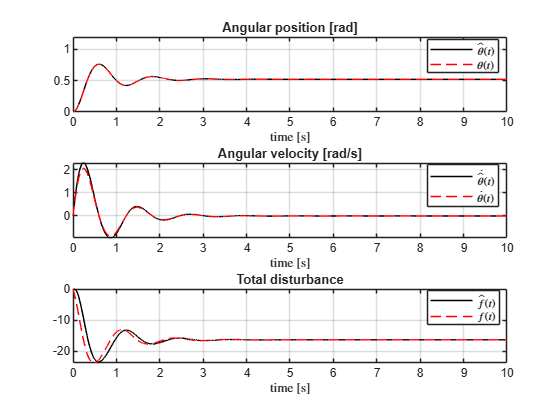

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

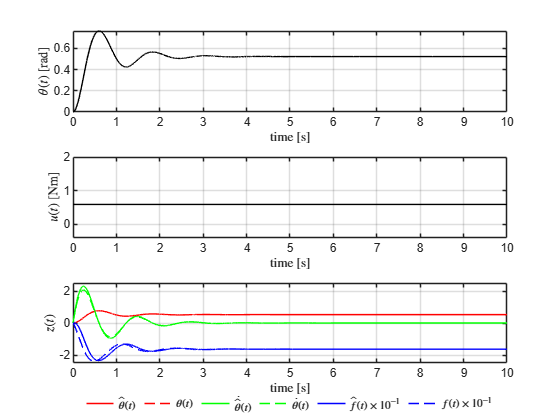

figure;
subplot(3,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(3,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-2.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) \times 10^{-1}$', '$f (t) \times 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

**Observation: **Note that now the total disturbance term is different from zero because the actual plant differes from the ideal double integrator plant. However, the ESO is doing a good job in properly estimating the states of the actual plant.

## 4. Closed-Loop Performance Analysis

### 4.1 Nominal Case with ADRC Control

**Configuration:**

- Control mode: ADRC enabled

- Initial conditions: `θ = 0 rad`, `θ_dot = 0 rad/s`

- Disturbance: Enabled

- Observer bandwidth: keso` = 20`

**Performance Assessment:**

- Verify settling within 5 seconds to 10% of setpoint

- Check disturbance rejection within 10% bounds

- Monitor control torque within 1 Nm peak-to-peak

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Enable ADRC controller
manual_control_flag = 0;

disturbance_flag = 1;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
keso =20

keso = 20

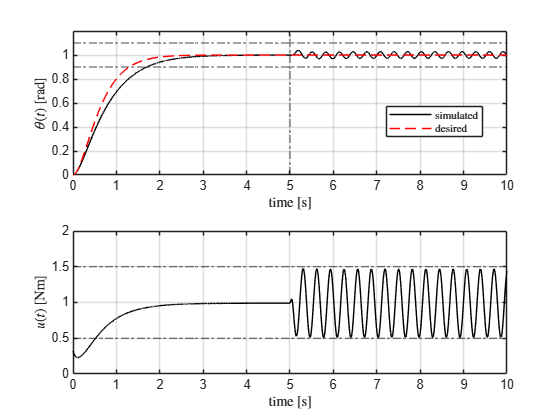

omega_o = keso*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

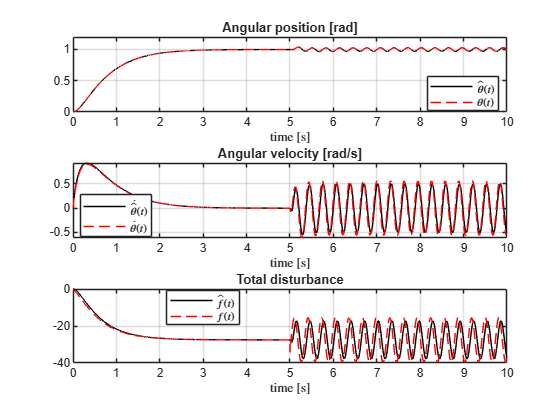

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

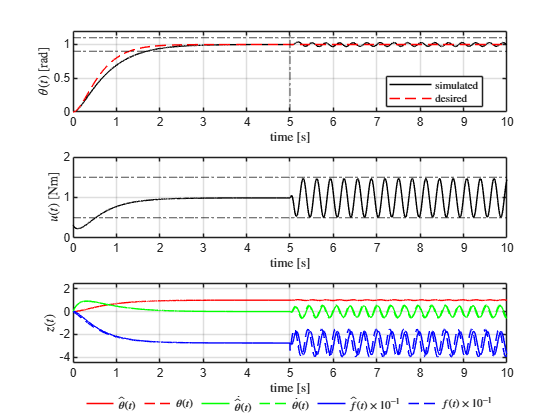

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) \times 10^{-1}$', '$f (t) \times 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

### **4.2 Effect of Sensor Noise**

Real sensors introduce measurement noise that affects control performance, particularly through the high-gain observer.

**Problem: **High observer bandwidth (`keso=20`) amplifies measurement noise into the control signal, causing excessive torque oscillations that violate the 1 Nm specification.

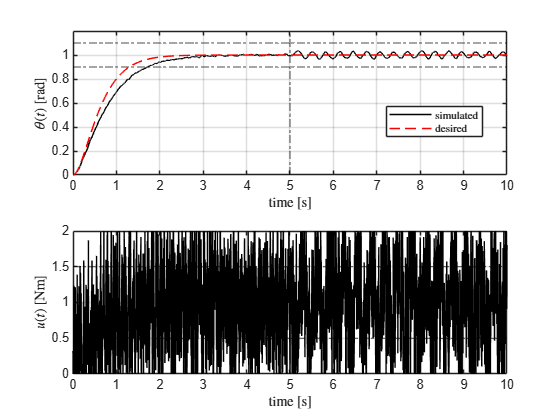

% Sensor noise
pow = 1e-6;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

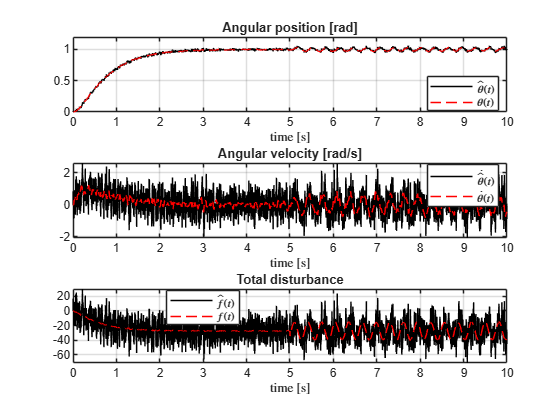

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

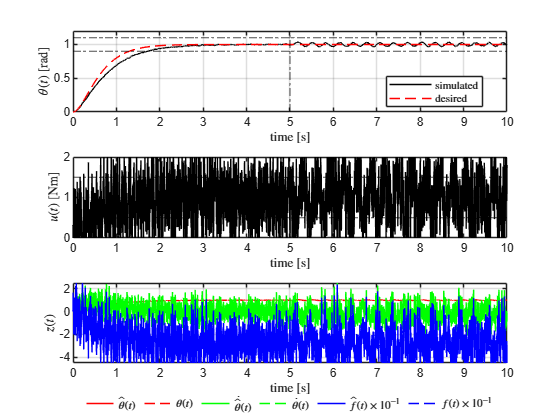

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) \times 10^{-1}$', '$f (t) \times 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

### **4.3 Noise-Robust Tuning Trade-off**

**Solution:** Reduce observer bandwidth to filter high-frequency noise while maintaining adequate disturbance rejection.

**Trade-off Analysis:**

- Lower bandwidth (`keso=7`): Smoother control action, better noise rejection

- Higher bandwidth (`keso=20`): Faster state estimation, better disturbance rejection

- Compromise: `keso=7` provides acceptable performance with compliant control effort

keso =7

keso = 7

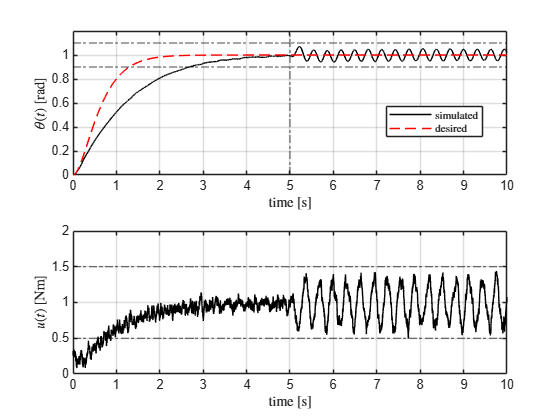

omega_o = keso*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

theta_nom = theta;
t_nom = t;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

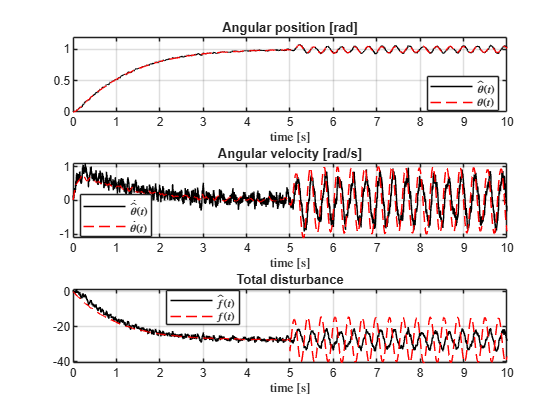

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

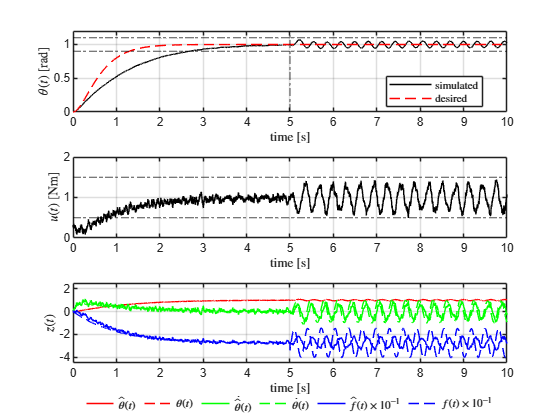

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) \times 10^{-1}$', '$f (t) \times 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

## 5. Performance Specification Change

### 5.1 Faster Set-Point Tracking

**New Specification:** Settling within 10% of setpoint in less than 2 seconds.

**Approach:** Increase controller bandwidth while maintaining observer ratio for noise immunity.

**Validation:** Verify that the faster response meets the new settling time requirement while maintaining acceptable control effort and disturbance rejection.

% ADRC tuning
% Desired closed-loop response characteristics
T_settle = 1.5;    %   [s] settling time 98%
xi = 1;     % desired closed-loop damping
omega_c = 6/T_settle;   % [rad/s] desired closed-loop bandwidth
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
keso =5

keso = 5

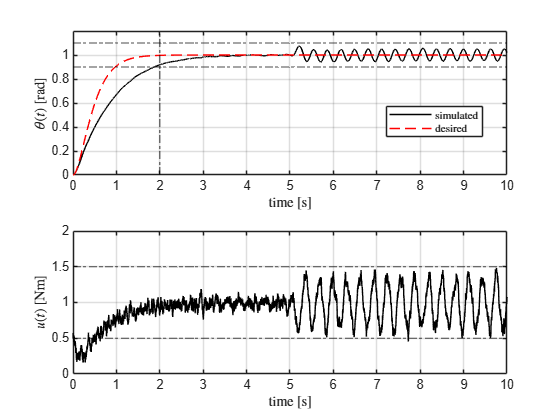

omega_o = keso*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(2, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

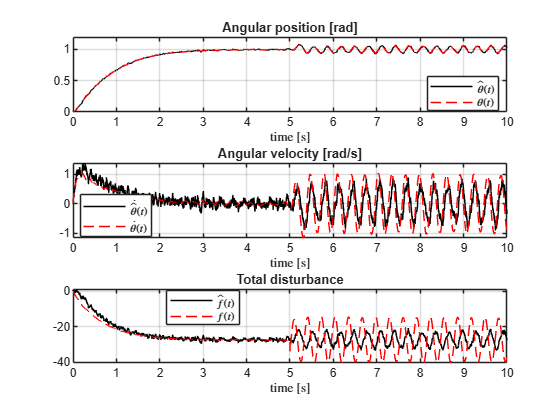

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

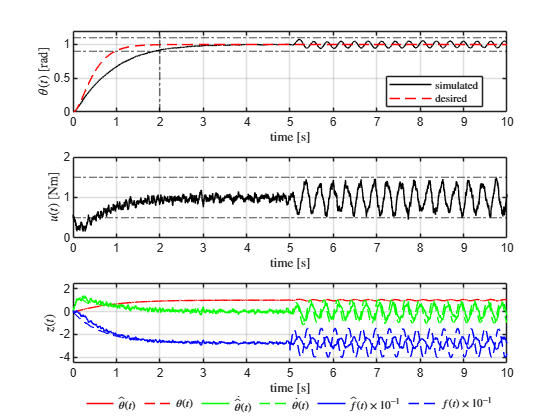

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(2, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) \times 10^{-1}$', '$f (t) \times 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

## 6. Conclusion

### 6.1 Summary of Results

The ADRC controller successfully meets all control specifications:

- Setpoint Tracking: Achieves required settling times (5s and 2s versions)

- Disturbance Rejection: Maintains oscillations within 10% of setpoint despite eccentric mass disturbance

- Control Effort: Maintains torque oscillations within 1 Nm peak-to-peak specification

- Noise Robustness: Proper observer tuning provides immunity to sensor noise

### **6.2 Key Insights**

- Observer Bandwidth Trade-off: Critical balance between estimation speed and noise sensitivity

- Model Independence: ADRC effectively handles unmodeled dynamics and disturbances

- Practical Tuning: Systematic approach to meeting multiple competing specifications

### **6.3 Final Controller Parameters**

For nominal performance with noise:

- Controller bandwidth: `ω_c = 3 rad/s`

- Observer ratio: `keo = 7`

- Settling time: ~2 seconds

For enhanced set-point racking performance:

- Controller bandwidth: `ω_c = 4 rad/s`

- Observer ratio: `keo = 5`

- Settling time: ~1.5 seconds